## Gráfica del campo escalar $\phi(x, y)$

% Datos del problema 
xOrg = 0; % Origen x-dir
yOrg = 0; % Origen y-dir
L = 1; % Longitud en las direcciones x e y

% Genereación del mallado 2D
x = xOrg:0.05:L;
y = yOrg:0.05:L;
[X, Y] = meshgrid(x, y);

% Cálculo del campo escalar
Phi = X.^2 - Y.^2;

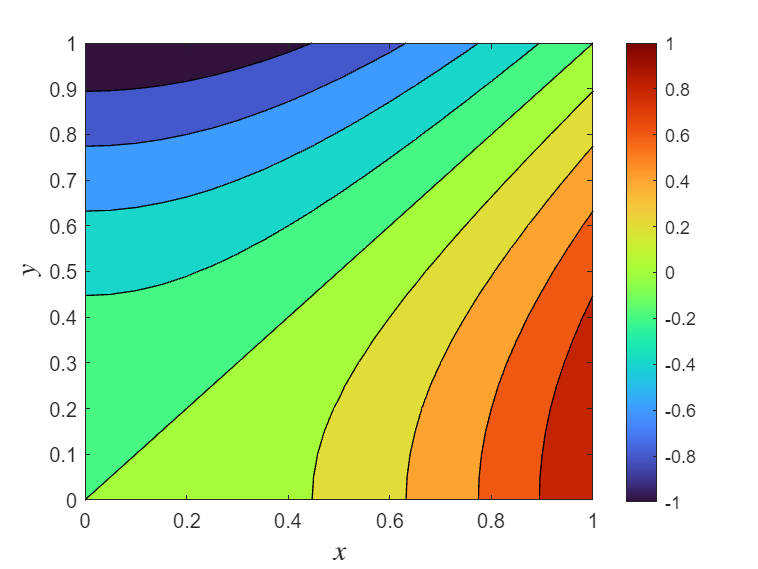

% Gráfica del campo escalar \phi
contourf(X, Y, Phi)
colorbar
colormap turbo
xlabel('$x$', 'Interpreter','latex', 'FontSize', 14)
ylabel('$y$', 'Interpreter', 'latex', 'FontSize', 14)

## Gráfica de la divergencia del campo 

% Cálculo del campo vectorial
phiX = 2*X; % Componente x del gradiente
phiY = -2*Y; % Component y del gradiente

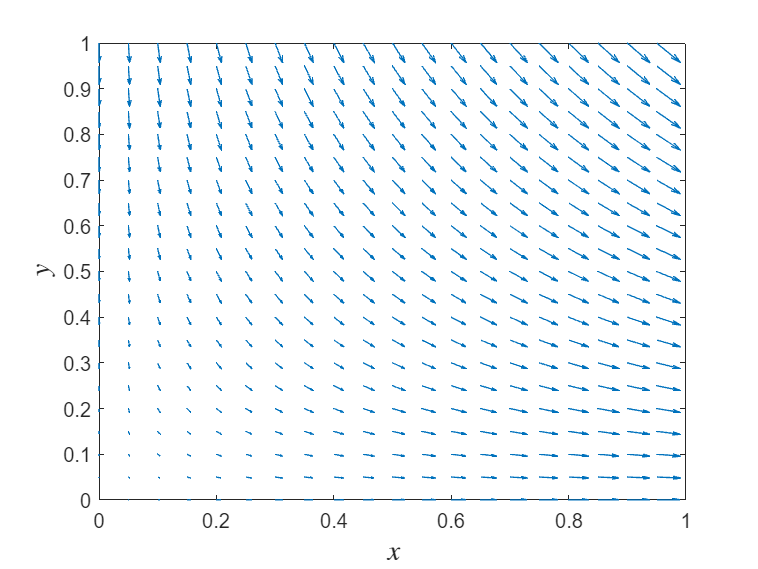

% Gráfica del campo vectorial
quiver(X, Y, phiX, phiY)
xlabel('$x$', 'Interpreter','latex', 'FontSize', 14)
ylabel('$y$', 'Interpreter', 'latex', 'FontSize', 14)
xlim([min(X(:)) max(X(:))]);
ylim([min(Y(:)) max(Y(:))]);